# **Homework 4 Orbital Dynamics**

Student 1: Mario Barrantes Mellado 100471762

Student 2: Artem Lorenzo Lymar 100471784

### Data of the problem:

close all; clear; clc;

% Initial conditions:

x0 = -0.001311;
y0 = 0.00001731;
z0 = 0.001011;

vx0 = -0.00008203;
vy0 = 0.008658;
vz0 = 0;


%% Constants
mu_star = 3.0034e-6;  % [-] Sun-Earth mass ratio (mu = M_Earth / (M_Sun + M_Earth))

% In the standard CR3BP non-dimensional formulation:
% - Sun  (mass 1-mu) is at x = -mu
% - Earth (mass  mu) is at x = 1-mu
% - L1 lies between them, closer to Earth


### (a) Find x position of L1

To find the L1 point, we solve for the roots of the collinear equilibrium condition. In the synodic frame, this point represents where the gravitational pull of the Sun and Earth perfectly balances the centrifugal force.

% Along the x-axis (y=z=0), the equilibrium condition is:
% x - (1-mu)/(x+mu)^2 + mu/(1-mu-x)^2 = 0
% This is a nonlinear equation solved numerically with fzero

f_L1 = @(x) x - (1-mu_star)./(x+mu_star).^2 + mu_star./(1-mu_star-x).^2;

x_L1 = fzero(f_L1, 0.99);  % initial guess close to Earth

fprintf('x_L1 = %.10f [-]\n', x_L1)

x_L1 = 0.9900266828 [-]


### (b) 

% Phi = functionshw4.STM(t, mu_star, x_L1)

### (c) Linear Stability and Trajectory Analysis

For this part, we compute matrix A and declare it global so that we can call it inside the STM funciton withouth modifying the header inputs. That way, the reader will find first the analysis on the eigenvalues and, right after, the trajectory computation.

% Distances from L1 to Sun and Earth (on x-axis, y=z=0)
rho1 = abs(mu_star + x_L1);        % [-] distance from Sun  (Sun is at x = -mu)
rho2 = abs(1 - mu_star - x_L1);    % [-] distance from Earth (Earth is at x = 1-mu)

K = (1 - mu_star)/rho1^3 + mu_star/rho2^3;
    
% Second derivatives of the effective potential at L1
    Uxx0 = -2*K - 1;
    Uyy0 = K - 1;
    Uzz0 = K; 
    Uxy0 = 0;
% Uxy = 0 because y = 0 at L1
global A
% Linearized equations of motion matrix
A = [ 0,    0,    0,    1,  0,  0;
      0,    0,    0,    0,  1,  0;
      0,    0,    0,    0,  0,  1;
     -Uxx0, -Uxy0, 0,    0,  2,  0;  % d_vx = -Uxx*x - Uxy*y + 2*vy
     -Uxy0, -Uyy0, 0,   -2,  0,  0;  % d_vy = -Uxy*x - Uyy*y - 2*vx
      0,    0,   -Uzz0,  0,  0,  0];


% Eigenvalue analysis
[V, D] = eig(A);
eigenvalues = diag(D);
disp('Eigenvalues of A:')

Eigenvalues of A:


disp(eigenvalues)

  -2.5326 + 0.0000i
   2.5326 + 0.0000i
   0.0000 + 2.0864i
   0.0000 - 2.0864i
   0.0000 + 2.0151i
   0.0000 - 2.0151i



### Discussion on stability:

**First Pair: **$\pm$$2.5326$

The most meaningful eigenvalue is the real pair: which indicates the stable and unstable manifolds, along which perturbations frow or decay exponentially. The spacecraft will eventually escape if no correction is applied.

**Second pair: **$\pm$$2.0864i$

The imaginary pair defines a center manifold, leading to the bounded in-plane oscillatory motion (in the xy plane), a Lyapunov orbit, around L1 with a frequency $\omega$$= 2.0864$. 

**Third pair: **$\pm 2.0151i$

This second imaginary pair corresponds to the out-of-plane oscillation (in the z direction), with a frequency $\omega = 2.0151$. These eigenvalues are exicted due to the non-zero initial conditions in $z_0$ non zero and $v_{z0}$, zero.

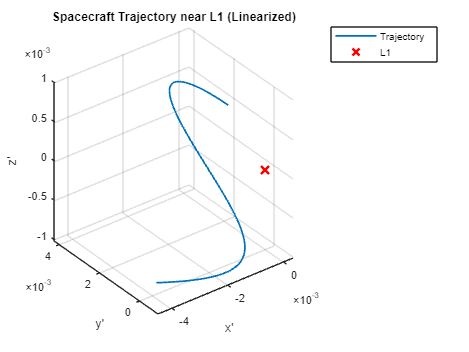

x0_rel = [x0,y0,z0,vx0,vy0,vz0]';
t_final = 2;
dt = 0.01;
time_vec = 0:dt:t_final;

% Calculate Trajectory
trajectory = zeros(6, length(time_vec));
for i = 1:length(time_vec)
    Phi = functionshw4.STM(time_vec(i));
    trajectory(:, i) = Phi * x0_rel;
end

figure;
plot3(trajectory(1,:), trajectory(2,:), trajectory(3,:), 'LineWidth', 1.5);
hold on;
plot3(0, 0, 0, 'rx', 'MarkerSize', 10, 'LineWidth', 2);  % L1 position
legend('Trajectory', 'L1');
grid on; 
xlabel('x'''); 
ylabel('y'''); 
zlabel('z''');
title('Spacecraft Trajectory near L1 (Linearized)');

### Commentary on the trajectory

The observed trajectory results from the superposition of the modes described above. As it is displayed in the plot above, the trajectory departs from the L1 point due to the excitation of the unsatble eigenmode. Althought oscillaotry motion is present due to the complex eigenvalues, the exponential growth dominates overt time, causing the trajectory to drift away from the equilibrium point.

### (d) Two Impulse Maneuver 

We apply a two-impulse strategy to transition the spacecraft to a stable state at $t_f = 0.5$.

**First Impulse**: We solve a targeting problem. Given the desired position $r_f$ at $t_f$, we calculate the required initial velocity $v_0^+$ using the partitioned STM, efectively a linear boundary value problem. The first impulse should modify the initial velocity to this required one.

**Second Impulse:** To ensure the spacecraft remains near L1 indefinitely, we must project the state onto the **stable manifold**. This is done by transforming the state into the eigenvector basis and solving for a velocity $v_f^+$ that sets the coefficient of the unstable eigenvalue to zero. 

Basically, this second impulse removes the component along the unstable eigenvector, ensuring that the resulting motion lies on the center manifold, where the dynamics are bounded and oscillatory.

xf = 0.001;
yf = 0.001;
zf = 0;

% 1. Get STM at tf
Phi_tf = functionshw4.STM(0.5, mu_star, x_L1);
Phi_rr = Phi_tf(1:3, 1:3);
Phi_rv = Phi_tf(1:3, 4:6);
Phi_vr = Phi_tf(4:6, 1:3);
Phi_vv = Phi_tf(4:6, 4:6);

% 2. First impulse
rf_target = [xf; yf; zf];
v0_plus = Phi_rv \ (rf_target - Phi_rr * x0_rel(1:3));
dv1 = v0_plus - x0_rel(4:6);

% 3. State before second impulse
vf_minus = Phi_vr * x0_rel(1:3) + Phi_vv * v0_plus;

disp('Eigenvalues (check order):')

Eigenvalues (check order):


disp(diag(D))

  -2.5326 + 0.0000i
   2.5326 + 0.0000i
   0.0000 + 2.0864i
   0.0000 - 2.0864i
   0.0000 + 2.0151i
   0.0000 - 2.0151i



% Find indices of real eigenvalues
real_idx = find(abs(imag(diag(D))) < 1e-10);
disp('Real eigenvalue indices:'); disp(real_idx)

Real eigenvalue indices:
     1
     2



% 4. Stability Target (The "Stable Orbit" part)
% Use the rows of V_inv corresponding to real eigenvalues
M = inv(V);
% Since index 1 and 2 are the real eigenvalues:
M_sub = M(real_idx, 4:5);                              % vx, vy columns
rhs   = -M(real_idx, 1:3) * rf_target;                % all 3 position components
vf_planar_plus = M_sub \ rhs;

% velocity right after the engiens start.
v_f_plus = [vf_planar_plus; 0]; % [vxf, vyf, vzf=0]
dv2 = v_f_plus - vf_minus;

### (e) Divergence and Non-Linear Effects

We compare the linear propagation (using the STM) against the non-linear dynamics (using $\texttt{ode45}$).

%% Part (e): Linear vs Non-Linear Propagation
t_start = 0.5;
t_end = 3; % <-- Propagate longer to see the divergence
t_span = t_start:0.01:t_end;

% Initial state in S1_1 frame (relative to L1)
x_f_plus = [xf; yf; zf; v_f_plus];

%% 1. Linearized Trajectory (Using the Hint: Eigenvector Basis)
% Using the eigenvector basis prevents numerical noise from 
% artificially "tripping" the unstable eigenvalue.
[V, D] = eig(A);
lambdas = diag(D);
c_new = V \ x_f_plus; 

traj_lin = zeros(6, length(t_span));
for i = 1:length(t_span)
    % Shift time by t_start since we start at tf=0.5
    dt_eval = t_span(i) - t_start;
    traj_lin(:, i) = V * (exp(lambdas * dt_eval) .* c_new);
end

%% 2. Non-linear Trajectory (Using ode45)
% We must define the non-linear equations from Slide 14
options = odeset('RelTol', 1e-12, 'AbsTol', 1e-12);
[t_out, traj_nonlin_bary] = ode45(@(t, s) functionshw4.cr3bp_ode(t, s, mu_star), t_span, ...
    [x_L1 + xf; yf; zf; v_f_plus], options);

% Convert non-linear results back to S1_1 frame (relative to L1)
traj_nonlin = traj_nonlin_bary';
traj_nonlin(1, :) = traj_nonlin(1, :) - x_L1;

% 3. Calculate Error
pos_error = sqrt(sum((traj_lin(1:3, :) - traj_nonlin(1:3, :)).^2, 1));

### Plot and Results:

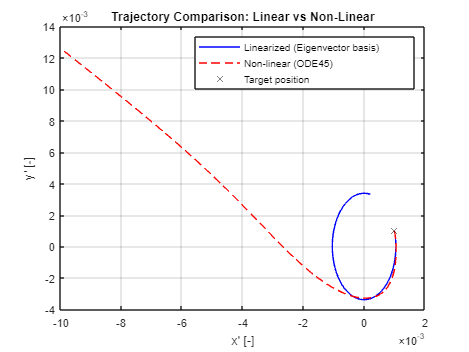

% Trajectory comparison
figure;
plot(traj_lin(1,:), traj_lin(2,:), 'b'); hold on;
plot(traj_nonlin(1,:), traj_nonlin(2,:), 'r--');
plot(xf, yf, 'kx', 'MarkerSize', 8);
legend('Linearized (Eigenvector basis)', 'Non-linear (ODE45)', 'Target position');
xlabel('x'' [-]'); ylabel('y'' [-]');
title('Trajectory Comparison: Linear vs Non-Linear');
grid on; hold off;

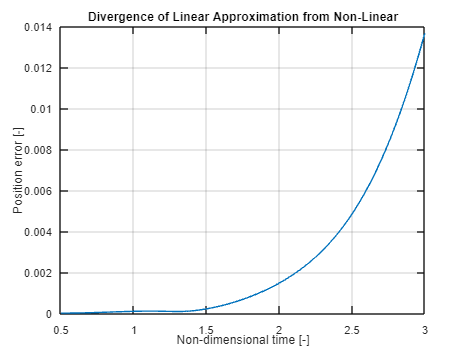

% Position error over time
figure;
plot(t_span, pos_error);
xlabel('Non-dimensional time [-]');
ylabel('Position error [-]');
title('Divergence of Linear Approximation from Non-Linear');
grid on;

### Results and Observations:

For small deviations and short time scales, the linear approximation is highly effective for maneuver planning.

As expected in a chaotic three body system, the position error grows significantly, even exponentially, over time. Specifically, after a non-dimensional time of $t \approx 1.5$, the non-linear perturbations and the higher-order gravity gradients cause the position error to grow exponentially large.

## Copilot AI

Copilot AI was used throughout the realization of this homework. It was used specifically to understand the homework's wording, and as aiding in the implementation of the theory found in the slides into MATLAB. The promps had to be modified but we found a good way to get straight forwards answer most of the time after a couple of tries. Promts as the following were used: "Using these slides, implement equation "A" going step by step and defining everything explicitly". This gave us a clear idea of how to do the program. Finally, Copilot aided to compact the code, found redundant lines of code as well as debugging.